%Скрипт для проверки особенностей и визуализации
%       функций правой части и поддифференициальной функции
clc, clear all;
N = 51;
M = 1000;

l = 1;
gamma = 100;
T = 1;


h = l/N;
tau = T/M;

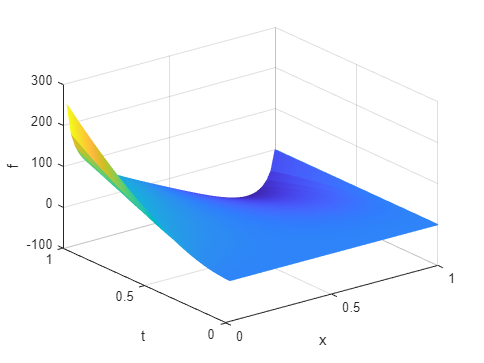

mu1 = @(t) 1 * t + 0.01;
mu2 = @(x) ((l-x).*(x+1))/l;

u = @(x,t) (t + 0.01).*((l-x).*(x+1)/l);

dmu1 = @(t) 1;
dmu2 = @(x) 1 - 2*x/l - 1/l;
d2mu2 = @(x) -2/l;


[x,t] = meshgrid(0:h:l, 0:tau:T);
z = FCalc(mu1, mu2, dmu1, dmu2, d2mu2, gamma,l, x, t);

mesh(x,t,z);
xlabel('x')
ylabel('t')
zlabel('f')

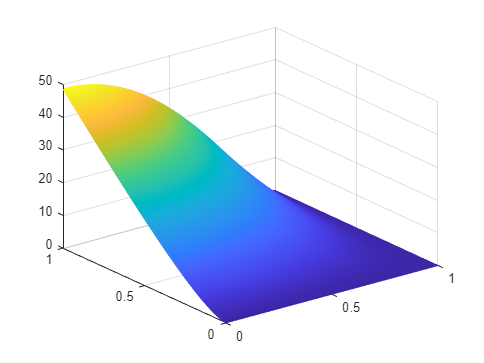


zpsi = PsiFunc(u(x,t), gamma, l);

mesh(x,t,zpsi);